# Statistics simulations

Fixed n_drone, variable time of simulation

% DRONE T SIMULATION %COVERED

sim_matrix = [];

directory = 'Simulation_data';

fileList = dir(fullfile(directory, 'data_sim_*.txt'));

for k = 1:length(fileList)
    fileName = fullfile(directory, fileList(k).name);
    data_sim = dlmread(fileName, ';');
    sim_matrix = [sim_matrix; data_sim];
end

sim_matrix_sorted = sort(sim_matrix)

sim_matrix_sorted =     1.0000   10.0000   12.7270
    1.0000   10.0000   17.9800
    1.0000   10.0000   26.2630
    1.0000   10.0000   33.6040
    1.0000   10.0000   33.9390
    1.0000   20.0000   43.2320
    1.0000   20.0000   44.6460
    1.0000   20.0000   47.0710
    1.0000   20.0000   48.6870
    1.0000   20.0000   49.5770


Plot the data

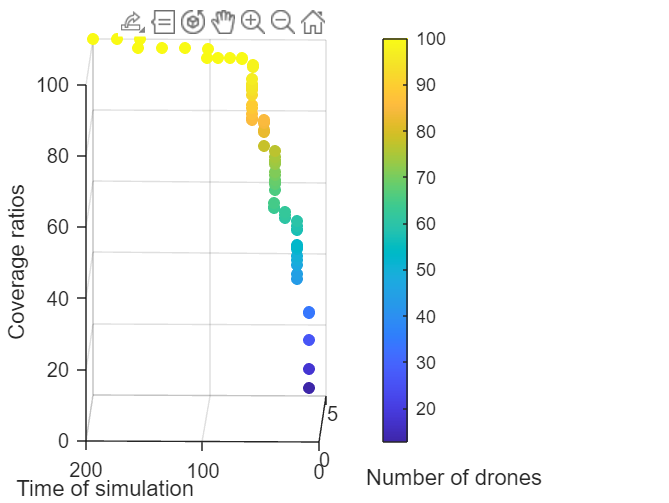

% Assumiamo che sim_matrix_sorted sia una matrice Nx3
x = sim_matrix_sorted(:, 1);
y = sim_matrix_sorted(:, 2);
z = sim_matrix_sorted(:, 3);

% Creare lo scatter plot 3D
s = scatter3(x, y, z, [], z, 'filled');
colorbar;
% Etichettare gli assi
xlabel('Number of drones');
ylabel('Time of simulation');
zlabel('Coverage ratios');
zlim([0 100]);

control_val_drone = sim_matrix_sorted(1, 1);
control_val_time = sim_matrix_sorted(2, 1);
for i = 2:length(sim_matrix_sorted)
    if sim_matrix_sorted(i, 1) == sim_matrix_sorted(i-1, 1) && ...
            sim_matrix_sorted(i, 2) == sim_matrix_sorted(i-1, 2)
        
    end

end


% Creazione di un fit polinomiale di quarto grado
ft = fittype('poly44'); % Polinomio di quarto grado nelle variabili x e y
fitresult = fit([x, y], z, ft);

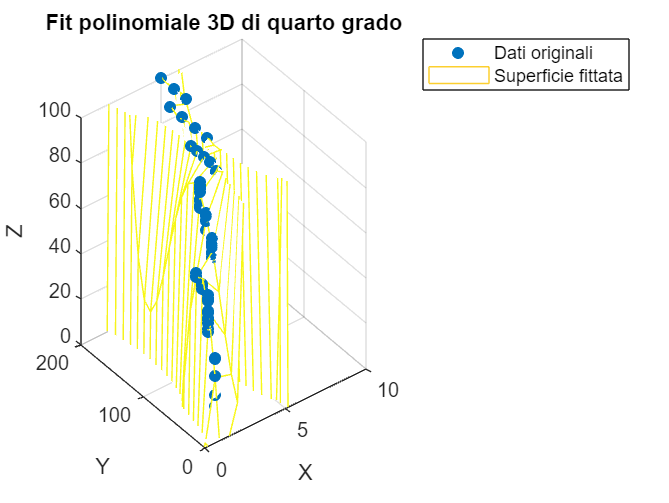


% Visualizzazione dei risultati del fit
% Creazione di una griglia per la visualizzazione
[x_grid, y_grid] = meshgrid(0:1:10,0:10:200);
z_fit = feval(fitresult, x_grid, y_grid);

% Plot dei dati originali
figure;
scatter3(x, y, z, 'filled'); 
zlim([0 100]);
hold on;

% Plot della superficie fittata
mesh(x_grid, y_grid, z_fit);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Fit polinomiale 3D di quarto grado');
legend('Dati originali', 'Superficie fittata');
hold off;